# Seminar Biomedical Engineering and Related Fields

## SW9: Importing and Simulating 4D Cardiac Models for Electrical Impedance Analysis

#### Supervisor: VOSS Daniel

#### Students: COLYBES Elouan & JACQ Mathieu

This document intends to describe the given data, for the Obermeier 2024 paper.

First, we want to plot the volume curve, and its flux curve also:

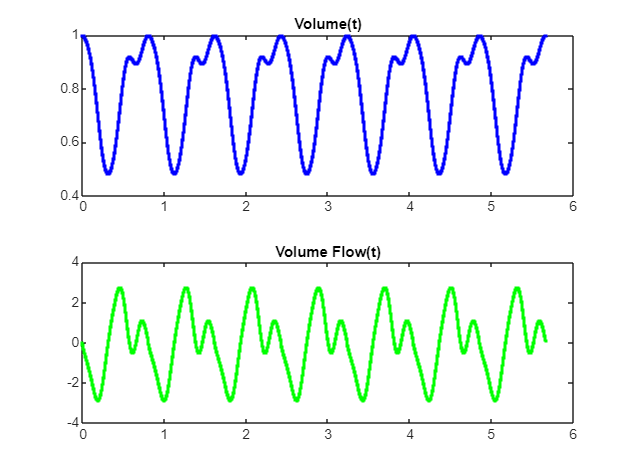

clf; clear;

subject = 3;    % can be 1,2,3

% Import the files
curve = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/VolumeCurve.csv'));
flux = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/VolumeFlux.csv'));


% Preparing plots
tiledlayout(2,1);

% Plotting volume
nexttile;
plot(curve(:,2),curve(:,1),'.',color='blue');
title('Volume(t)');

% Plotting flow
nexttile;
plot(flux(:,2),flux(:,1),'.',color='green');
title('Volume Flow(t)');

We can observe that the volume flow is the first derivative of the volume (it is also by definition).

Then, we wish to observe what the csv scatter plots looks like:

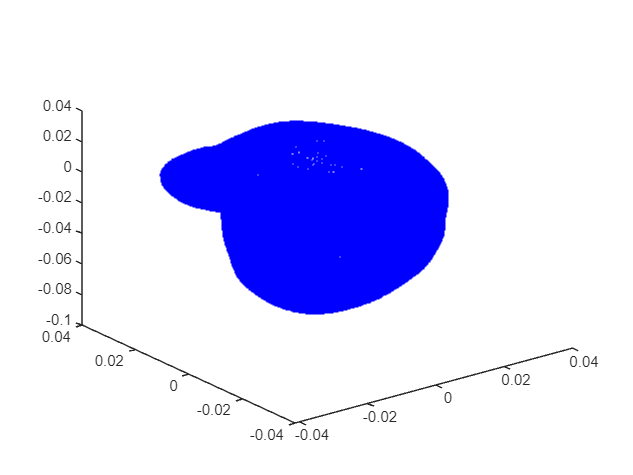

clf; clear;

subject = 3;    % can be 1,2,3
plot = 2;       % can be in 1:10

A = readmatrix(strcat('../data/subject',num2str(subject),'/FSI/displacement/GridVelocity_',num2str(plot-1),'.csv'));
% columns of A are X, Y, Z, vx, vy, vz

% Plotting the figure
plot3(A(:,1), A(:,2), A(:,3),'.',color='blue');

*Please note that the full-screen view offers a better vizualisation of the scatter plot. You can manipulate the figure in 3D as well.*

Now, we want to be able to generate a video showing the time evolution of the ventricle. For that purpose, we need to map the volume to a spatial position, at each time step. Two solutions are presented here: approximating to the floor known position ; or interpolating between two known solutions.

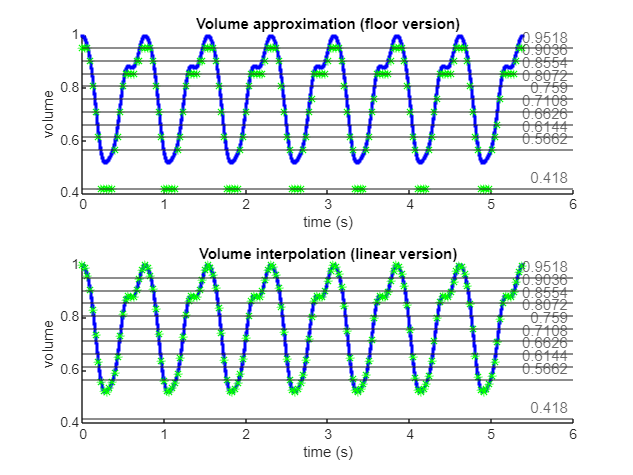

clf; clear;

subject = 1;    % can be 1,2,3

% Import files for data
path = strcat('..\data\subject',num2str(subject),'\FSI\displacement\');
intervol = readmatrix(strcat(path, 'IntermediateVolumesForDeformation.csv'));
volcurve = readmatrix(strcat(path, 'VolumeCurve.csv'));
indic = intervol(:,1);

% Function that will return the index of the upper bound plot,
% and percentage of distance to next plot
function [i,p] = which_plot(volume, indic)
    i = 0;                              % Plots # varying from 0 to 9
    while (volume < indic(i+1) & i<9)   % Test lower boundary
        i = i+1;
    end
    if (i > 0)
        p = (volume-indic(i))/(indic(i)-indic(i+1)); % Linear ratio between two figs
    else
        p = (volume-indic(i+1))/(indic(i+1)-indic(i+2)); % Linear ratio between two figs
    end
end

% The video has 30 FPS (AVI file constraint)
FPS = 30;
% The recording should respect given time
duration = volcurve(size(volcurve,1),2);

% How many frames we want to plot (+1 because we also want timestep 0)
n_frames = floor(duration*FPS)+1;
% How many time steps we want to skip each time to respect real time
n_skip = floor(size(volcurve,1)/(n_frames-1));

% Matrices to record approximations values
interpolation_linear = zeros(n_frames,2);
approximation_floor = zeros(n_frames,2);

% Filling the matrices
for i = 1:n_frames
    [k,p] = which_plot(volcurve((i-1)*n_skip+1,1),indic);
    if (k > 0)
        interpolation_linear(i,1) = (indic(k)-indic(k+1))*p + indic(k);
    else
        interpolation_linear(i,1) = (indic(1)-indic(2))*p + indic(1);
    end
    interpolation_linear(i,2) = volcurve((i-1)*n_skip+1,2);

    approximation_floor(i,1) = indic(k+1);
    approximation_floor(i,2) = volcurve((i-1)*n_skip+1,2);
end

% We'll plot two figures for the two solutions
tiledlayout(2,1);
nexttile;
hold on;


%% Floor approximation
% Plotting volume
plot(volcurve(:,2),volcurve(:,1),'.',color='blue');
xlabel('time (s)');
ylabel('volume');
title('Volume approximation (floor version)');

% Plotting floor-value
plot(approximation_floor(:,2),approximation_floor(:,1), '*', color="green");

% Plotting boundaries
for i=1:size(intervol,1)
    yline(indic(i,1), '-', indic(i,1));
end

hold off;
nexttile;
hold on;


%% Linear interpolation
% Plotting volume
plot(volcurve(:,2),volcurve(:,1),'.',color='blue');
xlabel('time (s)');
ylabel('volume');
title('Volume interpolation (linear version)');

% Plotting interpolate-value
plot(interpolation_linear(:,2),interpolation_linear(:,1), '*', color="green");

% Plotting boundaries
for i=1:size(intervol,1)
    yline(indic(i,1), '-', indic(i,1));
end

hold off;

By construction, the linear interpolation gives a better image of the position at each time step. However, we still don't know if it is truly accurate.

To this extent, let's plot a few random points from the heart model of a subject, and observe their spatial dispalcement along with the figures' number:

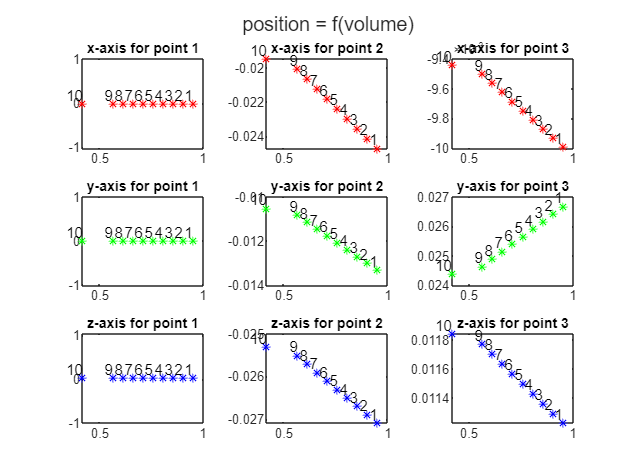

clf; clear;

subject = 1;    % Can be 1,2,3

% Importing data
path = strcat('..\data\subject',num2str(subject),'\FSI\displacement\');
intervol = readmatrix(strcat(path,'IntermediateVolumesForDeformation.csv'));

grid_velocity = cell(1,10);
for i = 1:10
    grid_velocity{i} = readmatrix(strcat(path,'GridVelocity_',num2str(i-1),'.csv'));
end

n = size(grid_velocity{1},1);
indic = intervol(:,1);


% Select 3 points for which we want to plot the displacement
point1 = 61;
point2 = floor(rand()*n);
point3 = floor(rand()*n);

T1 = zeros(10,4);
T2 = zeros(10,4);
T3 = zeros(10,4);

% Get their positions
for i=1:10
    T1(i,1:3) = grid_velocity{i}(point1 , 1:3);
    T1(i,4) = i;
    T2(i,1:3) = grid_velocity{i}(point2 , 1:3);
    T2(i,4) = i;
    T3(i,1:3) = grid_velocity{i}(point3 , 1:3);
    T3(i,4) = i;
end


% Plot the figures
% 1st row is all x-axis
% 1st column is point 1
t = tiledlayout(3,3);
title(t,'position = f(volume)')
nexttile;

plot(indic,T1(:,1),'*',color='red');
hold on;
for i = 1:length(indic)
    text(indic(i), T1(i,1), num2str(T1(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("x-axis for point 1");
nexttile;

plot(indic,T2(:,1),'*',color='red');
hold on;
for i = 1:length(indic)
    text(indic(i), T2(i,1), num2str(T2(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("x-axis for point 2");
nexttile;

plot(indic,T3(:,1),'*',color='red');
hold on;
for i = 1:length(indic)
    text(indic(i), T3(i,1), num2str(T3(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("x-axis for point 3");
nexttile;

plot(indic,T1(:,2),'*',color='green');
hold on;
for i = 1:length(indic)
    text(indic(i), T1(i,2), num2str(T1(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("y-axis for point 1");
nexttile;

plot(indic,T2(:,2),'*',color='green');
hold on;
for i = 1:length(indic)
    text(indic(i), T2(i,2), num2str(T2(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("y-axis for point 2");
nexttile;

plot(indic,T3(:,2),'*',color='green');
hold on;
for i = 1:length(indic)
    text(indic(i), T3(i,2), num2str(T3(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("y-axis for point 3");
nexttile;

plot(indic,T1(:,3),'*',color='blue');
hold on;
for i = 1:length(indic)
    text(indic(i), T1(i,3), num2str(T1(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("z-axis for point 1");
nexttile;

plot(indic,T2(:,3),'*',color='blue');
hold on;
for i = 1:length(indic)
    text(indic(i), T2(i,3), num2str(T2(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("z-axis for point 2");
nexttile;

plot(indic,T3(:,3),'*',color='blue');
hold on;
for i = 1:length(indic)
    text(indic(i), T3(i,3), num2str(T3(i,4)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;
title("z-axis for point 3");